%% runs simulation with RSC --> HPC connections only

simtime = 30000;

dt = 1;

parms.N_neurons = 4;
parms.I_in = [3.35, 2.72, 3.36, 2.77]';
parms.W = [3.04,-1.5,0,0; 3.24,-0.5,0,0; 0,0,2.83,-1.5; 0,0,3.03,-0.5];
parms.LR = [0;0;0.103448;0.068955];
parms.beta = [-0.8;0.8];
parms.tau_r = [1;1;1;1];
parms.tau_a = [100;100;120;120];


parms.A0 = [2;2];
parms.Ak = [-20;20];


parms.k = [0.02;0.05;0.02;0.05];
parms.h = [0;12;0;12];
parms.n = 2;

parms.noiseamp =0.37;
parms.noisefreq = 0.05;

Y_sol = SSAdapt_run_delay(simtime,dt,parms);

[hpc, rsc, p_swr,down_start_time,up_start_time,SWR_indices] = mua_calculator(Y_sol);  

Schmidt


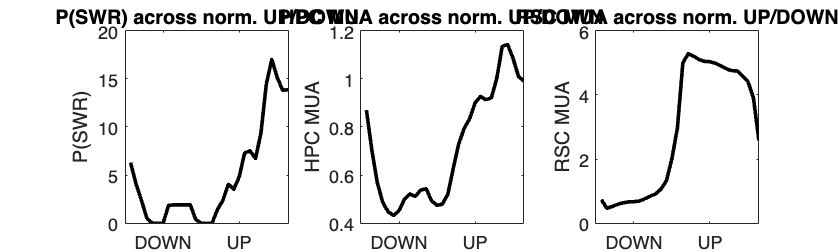


figure;
set(gcf, 'Position', [100 100 1000 300])
subplot(1,3,1)
    plot(p_swr','DisplayName','global','Color','black','LineWidth',2);
    ylabel('P(SWR)')
    xticks([14/2 14*3/2])
    xticklabels({"DOWN","UP"})
    set(gca, 'FontSize', 10);
    title("P(SWR) across norm. UP/DOWN")
subplot(1,3,2)
    plot(mean(hpc,1)','DisplayName','global','Color','black','LineWidth',2);
    ylabel('HPC MUA')
    xticks([14/2 14*3/2])
    xticklabels({"DOWN","UP"})
    %ylim([0 1])
    set(gca, 'FontSize', 10);
    title("HPC MUA across norm. UP/DOWN")
subplot(1,3,3)
    plot(mean(rsc,1)','DisplayName','global','Color','black','LineWidth',2);
    ylabel('RSC MUA')
    xticks([14/2 14*3/2])
    xticklabels({"DOWN","UP"})
    %ylim([0 1])
    set(gca, 'FontSize', 10);
    title("RSC MUA across norm. UP/DOWN")

%% runs simulation with HPC --> RSC connections only

simtime = 20000;

dt = 1;

parms.N_neurons = 4;
parms.I_in = [3.35, 2.72, 3.46, 2.87]';
parms.W = [3.04,-1.5,0,0; 3.24,-0.5,0,0; 0,0,2.83,-1.5; 0,0,3.03,-0.5];
parms.LR = [0.13793;0.724137;0;0];
parms.beta = [-0.8;0.8];
parms.tau_r = [1;1;1;1];
parms.tau_a = [100;100;120;120];


parms.A0 = [2;2];
parms.Ak = [-20;20];


parms.k = [0.02;0.05;0.02;0.05];
parms.h = [0;12;0;12];
parms.n = 2;

parms.noiseamp =0.37;
parms.noisefreq = 0.05;

Y_sol = SSAdapt_run_delay(simtime,dt,parms);

[hpc, rsc, p_swr,down_start_time,up_start_time,SWR_indices] = mua_calculator(Y_sol);  

Schmidt


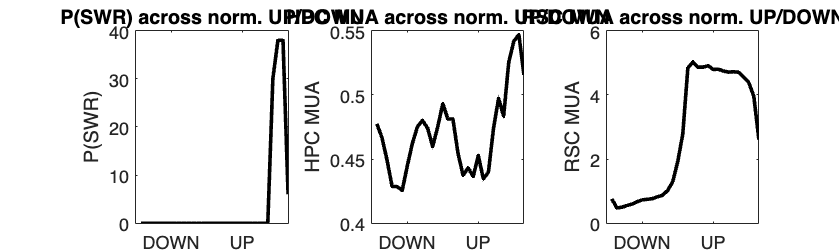


figure;
set(gcf, 'Position', [100 100 1000 300])
subplot(1,3,1)
    plot(p_swr','DisplayName','global','Color','black','LineWidth',2);
    ylabel('P(SWR)')
    xticks([14/2 14*3/2])
    xticklabels({"DOWN","UP"})
    set(gca, 'FontSize', 10);
    title("P(SWR) across norm. UP/DOWN")
subplot(1,3,2)
    plot(mean(hpc,1)','DisplayName','global','Color','black','LineWidth',2);
    ylabel('HPC MUA')
    xticks([14/2 14*3/2])
    xticklabels({"DOWN","UP"})
    %ylim([0 1])
    set(gca, 'FontSize', 10);
    title("HPC MUA across norm. UP/DOWN")
subplot(1,3,3)
    plot(mean(rsc,1)','DisplayName','global','Color','black','LineWidth',2);
    ylabel('RSC MUA')
    xticks([14/2 14*3/2])
    xticklabels({"DOWN","UP"})
    %ylim([0 1])
    set(gca, 'FontSize', 10);
    title("RSC MUA across norm. UP/DOWN")